# Library uolib user's guide (UG)

## Introduction

This livescript introduces library `uolib`, a collection of Matlab functions for the solution of unconstrained optimization problems following the lecture notes of the course.

The functions in this library are:

- Function `uosol`: unconstrained optimization solver, based on **Algorithm UOSOL** (**A1.1**).

- Function `uosolLog`: displays a iteration log of the results of funcition `uosol`.

- Function `uosolPlot`: plots the results of function `uosol`.

- Function `uoBLS`: backtracking linesear with Wolfe Conditions, `Algorithm BLS` (`A1.2`).

- Function `uoBLSPlot`: plots the results of function `uoBLS`.

- Function `uoQFsc`: definition of strictly convex quadratic function.

The following files are needed to work with the library:

- Templates [`uosol_st.m`](matlab:open('./uosol_st.m')) and [`uoBLS_st.m`](matlab:open('./uoBLS_st.m')) for the `st`udent's version of these functions. 

- The Matlab executables, content-obscured `.p `files,of all the functions in the library. These `.p `files can be called as the original `.m `source files filesbut the source code is hidden.

This `.mlx` must be run in the same folder as the functions `uolib`, or you must include the `uolib` folder in the [Matlab's path](https://es.mathworks.com/help/releases/R2024b/matlab/ref/path.html?searchHighlight=path&s_tid=doc_srchtitle).

For those without experience with Matlab, the following [MATLAB® Basic Functions Reference](https://www-eio.upc.es/~fjheredia/files/uo/uo_matlab_ref.pdf) can be handful to start with.

Table of contents

## Function `uosol`

uosol


 [sol,par] = uosol(P,x1,par)

 Unconstrained Optimization SOLver.

 Input:
  P          : f,g,h.
  x1         : first iterate.
  par (opt.) : optimization parameters.
 Output:
  sol        : information on each iteration "k".
  par        : omitted parameters with default values.
 Calls       : uoBLS, uosolLog.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% [sol,par] = uosol(P,x1,par)
%
% Unconstrained optimization with first and second derivative methods.
%
% Input:
%
% x1            : first iterate
% P             : problem
%   P.f         :   objective function.
%   P.g         :   gradient.
%   P.h         :   hessian.
% par (optional): optimization and auxiliary parameters
%   par.epsG    :   optimality tolerance ||g(x*)|| < epsG
%   par.maxiter :   maximum number of iterations.        
%   par.iAC     : acceptability conditions
%               :   = 0: ELS
%               :   = 1: BLS+WC
%               :   = 2: BLS+SWC
%               :   = 3: BLS+WC+DC (for CGM-PR+)
%   par.almax   :   initial trial step length.           
%   par.almin   :   minimum step length                  
%   par.rho     :   step lenght reduction.
%   par.c1      :   (WC1) coefficient.
%   par.c2      :   (WC2) ans (SWC2) coefficient.
%   par.isd     : search direction:
%               :   = 1: GM
%               :   = 2: CGM
%               :   = 3: BFGS
%               :   = 4: NM
%               :   = 5: MNM-SD
%               :   = 6: MNM-CMI.
%   par.icg     : CGM variant:
%               :   = 1: FR
%               :   = 2: PR+ 
%   par.irc     : Restart for the CGM:
%               :   = 0: no restart
%               :   = 1: (RC1)
%               :   = 2: (RC2)
%   par.nu      : parameter nu for the (RC2)
%   par.delta   : parameter delta in the MNM-CMI.
%   par.xo      : if known, optimizer (used in uosolLog to calculate r and M)
%   par.logfreq : log frequency.
%               :   > 0 : log every par.logfreq iter. with figures.
%               :   = 0 : suppress output (quiet mode).
%               :   < 0 : log every |par.logfreq| iter. without figures.
%
% Output:
%
% sol: information on each iteration
%   sol(k).x     :  x^k
%   sol(k).g     :  g(x^k)
%   sol(k).ng    :  ||g(x^k)||
%   sol(k).d     :  d^k
%   sol(k).al    :  alpha^k
%   sol(k).AC    :  "WC1", "WC", "SWC" ("***" if none)
%   sol(k).beta  :  beta^k
%   sol(k).H     :    H^K_BFGS........if par.isd=3..............(BFGS)
%                :    h(x^k)..........if par.isd=4..............(NM)   
%                :    B^k.............if par.isd=5,6............(MNM)
%   sol(k).la1   :  smallest eigenvalue
%                :    la1(H^k_BFGS)...if par.isd = 3............(BFGS)
%                :    la1(h(x^k)).....if par.isd = 4,5,6........(NM,MNM)
%   sol(k).kappa :  condition number
%                :    kappa(H^k_BFGS) if par.isd = 3............(BFGS)
%                :    kappa(h(x^k))...if par.isd = 4 and la1>0..(NM)
%                :    kappa(B^k)).....if par.isd = 5,6..........(MNM)
%   sol(k).r     : r^k = e(x^(k+1))/e(x^k)
%   sol(k).M     : M^k = e(x^(k+1))/e(x^k)^2
% par: undefined fields on input are loaded on exit with default values.
%
% Calls          : uoBLS, uosolLog.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Table of contents

### Input arguments.

#### `P, x1: `problem and first iterate.

The first step is to define the optimization problem: functions $f\left(x\right)$, $\nabla f\left(x\right)$ and $\nabla^2 f\left(x\right)$.

clear;
% Problem Ex2.2b
P.f = @(x) x(1)^2 + x(2)^3 + 3*x(1)*x(2);
P.g = @(x) [ 2*x(1)+3*x(2) ; 3*x(2)^2 + 3*x(1)];
P.h = @(x) [ 2 , 3; 3 , 6*x(2)];

and the first iterate $x^1 :$

x1 = [-3;-1]; % First iterate

Table of contents

#### `par: `optimization parameters.

Next, we define the parameters in the structure `par`. First, the parameters controlling the stopping conditions:

%clear par; par.logfreq = 0; [sol,par]=uosol(P,x1,par); par

par.epsG    = 10^-6; % optimality tolerance ||g(x*)|| < epsG
par.maxiter = 1500 ; % maximum number of iterations.

then the parameters for the line search:

par.almax = 2    ; % initial trial step length.
par.almin = 10^-3; % minimum step length
par.rho   = 0.5  ; % step lenght reduction.
par.c1    = 0.01 ; % (WC1) coefficient.
par.c2    = 0.5 ; % (WC2) and (SWC2) coefficient.
par.iAC   = 2    ; % Acceptability condition:
                   % = 0 : exact LS
                   % = 1 : BLS with WC
                   % = 2 : BLS with SWC;

and, finally, the parameters controlling the calculation of the descent direction:

par.isd   = 1    ; % search direction:
                   % = 1 : GM
                   % = 2 : CGM
                   % = 3 : BFGS
                   % = 4 : NM
                   % = 5 : MNM-SD
                   % = 6 : MNM-CMI.

par.isd   = 1 selects the GM ($d^k =-\nabla f^k$). 

Finally, there are three parameters related with the iterations log (see section below):

%   par.xo      : if known, optimizer (used in uosolLog to calculate r and M)
%   par.logfreq : log frequency.
%               :   > 0 : log every par.logfreq iter. with figures.
%               :   = 0 : suppress output (quiet mode).
%               :   < 0 : log every |par.logfreq| iter. without figures.

`uosol` assigns default values to all needed parameters that has not been previously defined.

Table of contents

### Standard output.

Once the optimization process is done, function `uosolLog` generates a standard output that will be sent to the console. This stabdard output includes an **iteration log** and several **graphs** showing the overall optimization process. These iteration log and graphs will be used to analyse the behaviour of the algorithms.

The **iteration log** is composed by a **header** and **information of the iterations**. The **header** prompts the problem, initial solution and optimization parameters:

% [uosolLog]
%    f= @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
%    epsG= 1.0e-06, kmax= 1500
%    iAC = 1 (WC)
%       almin= 1.0e-03, almax=  2, rho= 0.50, c1= 0.01, c2= 0.50
%    isd= 1 (GM)
%    ek = fk-f*
%    x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk

The **information of the iterations** is emitted every |`par.logfreq|` iterations (`=1` by default):

% k     g'*d        al  AC    ||g||        f         r        M
% 1 -1.2e+02 +2.50e-01 SWC +1.1e+01 +1.7e+01 +6.69e-02 +3.6e-03
% 2 -2.2e+00 +2.50e-01 SWC +1.5e+00 -4.4e-01 +7.61e-01 +6.1e-01
% 3 -1.3e+00 +5.00e-01 SWC +1.1e+00 -7.4e-01 +7.09e-01 +7.5e-01
% 4 -3.1e+00 +2.50e-01  WC +1.8e+00 -1.0e+00 +7.44e-01 +1.1e+00

The amount of information depends on the algorithm, as explained in the description of the function `uosolLog`.

%   k        : iteration number
%   g'*d     : g^k'*d^k
%   al       : alpha^k
%   AC       : acceptability of alpha^k
%            :   = *** : no WC satisfied.
%            :   = WC1 : (WC1) only
%            :   = WC  : (WC).
%            :   = SWC : (SWC).
%   ||g||    : ||g^k||.
%   f        : f^k.
%   r        : r^k = e(x^(k+1))/e(x^k).
%   M        : M^k = e(x^(k+1))/e(x^k)^2.
%   la_1     : la_1(H^k_BFGS)...if par.isd=3..............(BFGS)
%            : la_1(h(x^k)).....if par.isd=4..............(NM)
%            : la_1(B^k)........if par.isd=5,6............(MNM)
%   kappa    : kappa(H^k_BFGS)..if par.isd=3..............(BFGS)
%            : kappa(h(x^k))....if par.isd=4 and la_1>0...(NM)
%            : kappa(B^k).......if par.isd=5,6............(MNM)
%   del./tau : delta^k..........if par.isd=5..............(MNM-SD)
%            : tau^k............if par.isd=6..............(MNM-SD)

The **graphs** includes

- if $n=2$ the evolution of the algorithm, with and without the surface of $f\left(x\right)$.

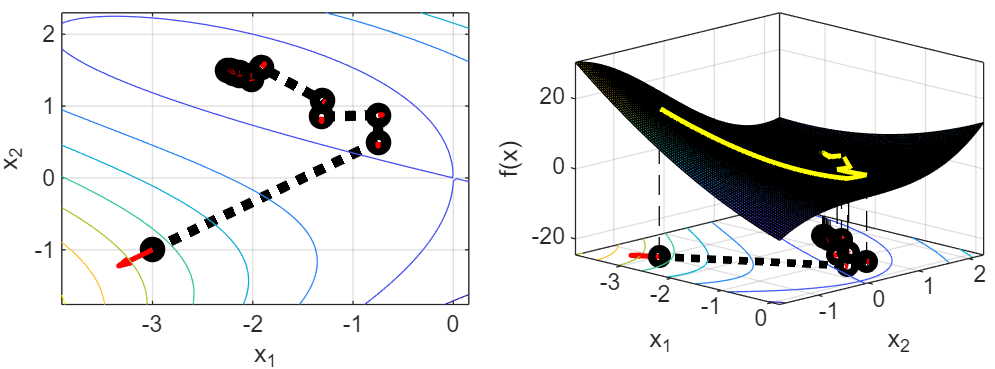

- Always: the evolution of $r^k$ and $\alpha^k$.

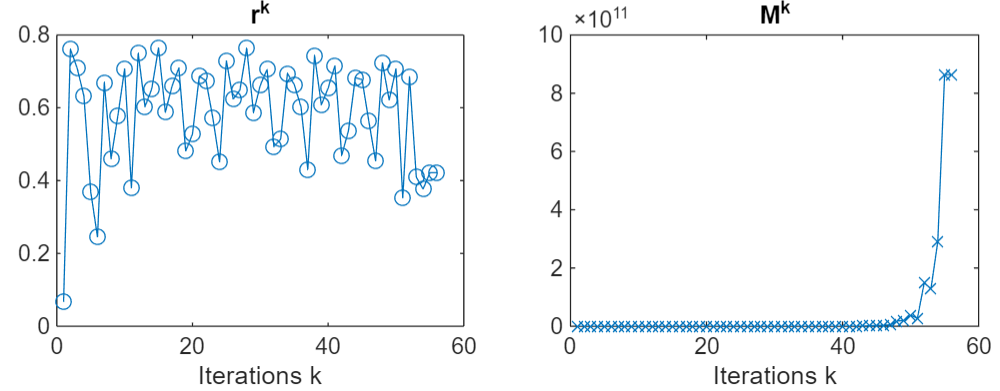

If `par.logfreq<1` the graphs are omitted.

Table of contents

#### **Gradient method.**

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter = 1500
   iAC = 2 (SWC)
      almin = 1.0e-03, almax =  2.00, rho = 0.50, c1 = 0.01, c2 = 0.50
   isd = 1 (G)M
   ek = fk-f*
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC    ||g||        f         r        M
      1 -1.2e+02 +2.50e-01 SWC +1.1e+01 +1.7e+01 +6.69e-02 +3.6e-03
      2 -2.2e+00 +2.50e-01 SWC +1.5e+00 -4.4e-01 +7.61e-01 +6.1e-01
      3 -1.3e+00 +5.00e-01 SWC +1.1e+00 -7.4e-01 +7.09e-01 +7.5e-01
      4 -3.1e+00 +1.25e-01 SWC +1.8e+00 -1.0e+00 +6.32e-01 +9.4e-01
      5 -5.9e-01 +1.00e+00 SWC +7.7e-01 -1.3e+00 +3.70e-01 +8.7e-01
     48 -1.3e-10 +2.50e-01 SWC +1.1e-05 -1.7e+00 +7.24e-01 +1.8e+10
     49 -1.8e-10 +1.25e-01 SWC +1.3e-05 -1.7e+00 +6.21e-01 +2.1e+10
     50 -4.3e-11 +5.00e-01 SWC +6.5e-06 -1.7e+00 +7.07e-01 +3.8e+10
     51 -1.7e-10 +1.25e-01 SWC +1.3e-05 -1.7e+00 +3.53e-01 +2.7e+10
     52 -1.9e-11 +1.25e-01 SWC +4.4e-06 -1.7e+00 +6.86e

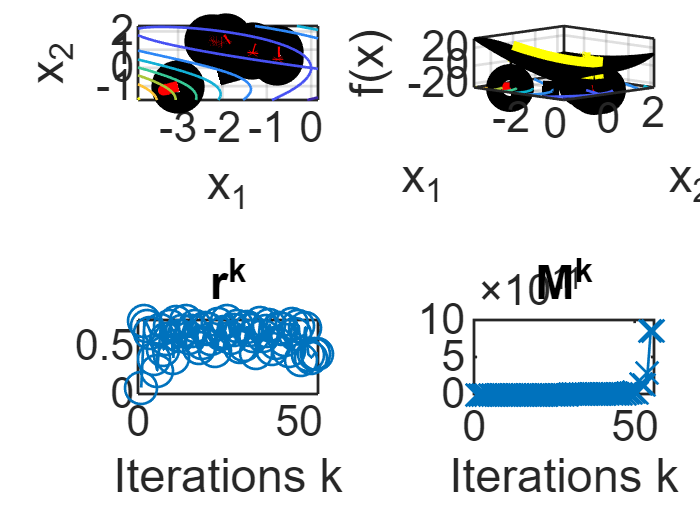

par.isd = 1;     % GM selected
uosol(P,x1,par); % run the algorithm

Table of contents

#### **Quasi-Newton method.**

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter = 1500
   iAC = 2 (SWC)
      almin = 1.0e-03, almax =  2.00, rho = 0.50, c1 = 0.01, c2 = 0.50
   isd = 3 (BFGS)
   ek = fk-f*
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC   la1(H)     k(H)  cos(th)    ||g||        f         r        M
      1 -1.2e+02 +2.50e-01 SWC +1.0e+00 +1.0e+00 +1.0e+00 +1.1e+01 +1.7e+01 +6.69e-02 +3.6e-03
      2 -2.0e+00 +5.00e-01 SWC +2.7e-01 +3.9e+00 +9.5e-01 +1.5e+00 -4.4e-01 +6.74e-01 +5.4e-01
      3 -5.1e-01 +2.00e+00 SWC +1.1e-01 +7.5e+00 +7.7e-01 +2.0e+00 -8.5e-01 +2.57e-01 +3.1e-01
      4 -6.4e-01 +5.00e-01 SWC +1.2e-01 +1.5e+01 +8.6e-01 +6.8e-01 -1.5e+00 +6.03e-02 +2.8e-01
      5 -2.9e-02 +1.00e+00 SWC +1.1e-01 +1.2e+01 +8.3e-01 +1.8e-01 -1.7e+00 +2.96e-02 +2.3e+00
      6 -8.5e-04 +1.00e+00 SWC +1.2e-01 +9.8e+00 +6.2e-01 +5.2e-02 -1.7e+00 +1.69e-02 +4.4e+01
      7 -1.3e-05 +1.00e+00 SWC +1.0e-01 +1.1e+01 +8.3e-01 +1.1e-02 -

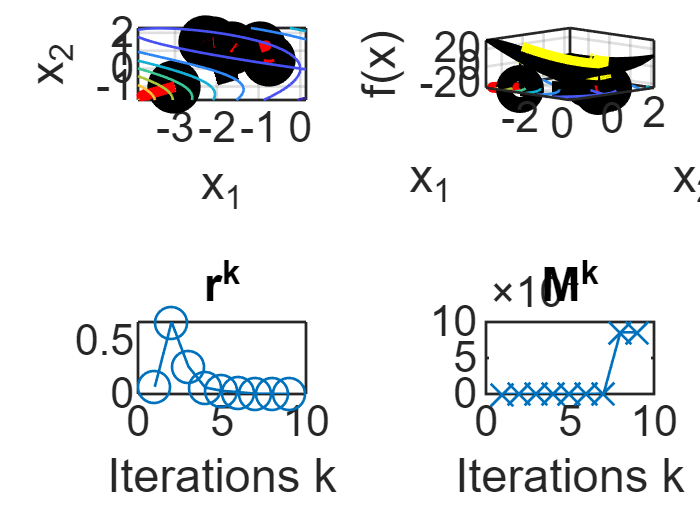

par.isd = 3;     % QNM selected
uosol(P,x1,par); % run the algorithm

Table of contents

#### **Newton method.**

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter = 1500
   isd = 4 (NM): al = 1
   ek = ||gk||
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al   la1(h)     k(h)    ||g||        f         r       M
      1 -3.5e+01 +1.00e+00 -7.0e+00  undef.  +1.1e+01 +1.7e+01 +1.42e-01 +1.3e-02
      2 +3.8e-01 +1.00e+00 -3.4e+00  undef.  +1.5e+00 -2.1e-01 +1.19e-01 +7.8e-02
      3 +7.0e-03 +1.00e+00 -2.3e+00  undef.  +1.8e-01 -3.6e-03 +2.43e-02 +1.3e-01
      4 +4.4e-06 +1.00e+00 -2.2e+00  undef.  +4.4e-03 -2.2e-06 +6.55e-04 +1.5e-01
      5 +1.9e-12 +1.00e+00 -2.2e+00  undef.  +2.9e-06 -9.3e-13 +4.29e-07 +1.5e-01
      6                    -2.2e+00  undef.  +1.2e-12 -1.7e-25
      k     g'*d        al   la1(h)     k(h)    ||g||        f         r        M
   x* = [ +4.2e-13 , -2.8e-13 ]
   [uosolLog]


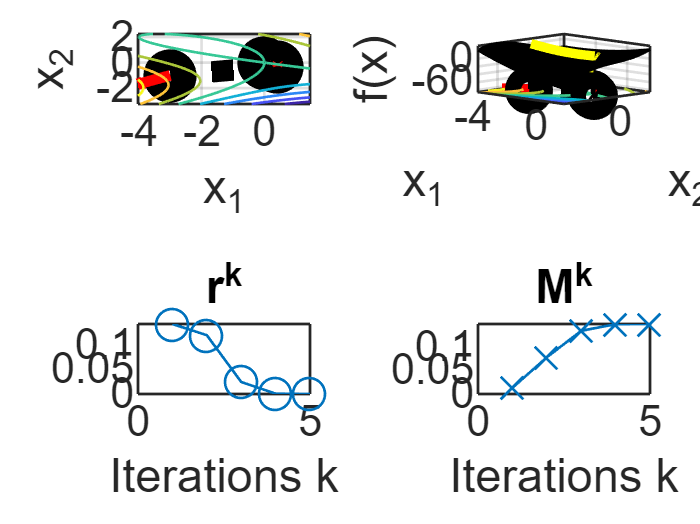

par.isd = 4;     % NM selected
uosol(P,x1,par); % run the algorithm

Table of contents

#### **Modified Newton Method - SD.**

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter = 1500
   iAC = 2 (SWC)
      almin = 1.0e-03, almax =  2.00, rho = 0.50, c1 = 0.01, c2 = 0.50
   isd = 5 (MNM-SD)
      delta = 1.0e-03
   ek = ||gk||
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC   la1(h)      delta     k(B)    ||g||        f         r        M
      1 -8.1e+03 +9.77e-04 WC1 -7.0e+00 <  1.0e-03 +3.0e+03 +1.1e+01 +1.7e+01 +4.22e-01 +3.9e-02
      2 -4.1e+00 +1.00e+00 SWC +9.8e-01 >= 1.0e-03 +1.1e+01 +4.6e+00 +3.7e-01 +1.06e-02 +2.3e-03
      3 -5.1e-04 +1.00e+00 SWC +9.0e-01 >= 1.0e-03 +1.1e+01 +4.8e-02 -1.7e+00 +6.98e-03 +1.4e-01
      4 -2.5e-08 +1.00e+00 SWC +8.9e-01 >= 1.0e-03 +1.1e+01 +3.4e-04 -1.7e+00 +5.01e-05 +1.5e-01
      5                        +8.9e-01                     +1.7e-08 -1.7e+00
      k     g'*d        al  AC   la1(h)      delta     k(B)    ||g||        f         r        M
   x* = [ -2.3e+00 , +1.5e+00 ]
   [uosolLog]


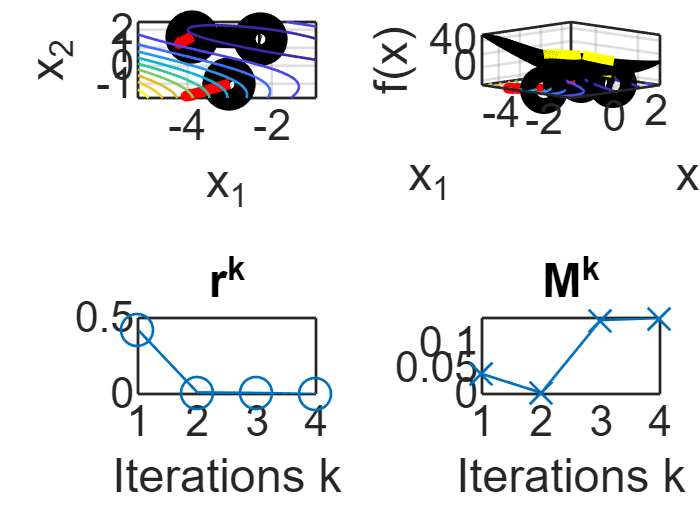

par.isd = 5;     % MNM-SD selected
uosol(P,x1,par); % run the algorithm

Table of contents

#### **Modified Newton Method - CMI.**

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter = 1500
   iAC = 2 (SWC)
      almin = 1.0e-03, almax =  2.00, rho = 0.50, c1 = 0.01, c2 = 0.50
   isd = 6 (MNM-CMI)
   ek = ||gk||
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC   la1(h)      tau     k(B)    ||g||        f         r        M
      1 -4.8e+01 +9.77e-04 WC1 -7.0e+00 +7.2e+00 +4.7e+01 +1.1e+01 +1.7e+01 +1.00e+00 +9.3e-02
      2 -4.8e+01 +9.77e-04 WC1 -6.9e+00 +7.2e+00 +4.5e+01 +1.1e+01 +1.7e+01 +1.00e+00 +9.2e-02
      3 -4.8e+01 +2.50e-01 SWC -6.9e+00 +7.1e+00 +4.2e+01 +1.1e+01 +1.7e+01 +1.79e-01 +1.6e-02
      4 -2.4e+00 +1.00e+00 SWC +1.2e+00 +0.0e+00 +1.1e+01 +1.9e+00 -3.7e-01 +2.95e-01 +1.5e-01
      5 -6.3e-02 +1.00e+00 SWC +9.7e-01 +0.0e+00 +1.1e+01 +5.7e-01 -1.7e+00 +6.33e-02 +1.1e-01
      6 -2.9e-04 +1.00e+00 SWC +9.0e-01 +0.0e+00 +1.1e+01 +3.6e-02 -1.7e+00 +5.26e-03 +1.5e-01
      7 -8.1e-09 +1.00e+00 SWC +8.9e-01 +0.0e+00 +1.1e+01 +1.9e-

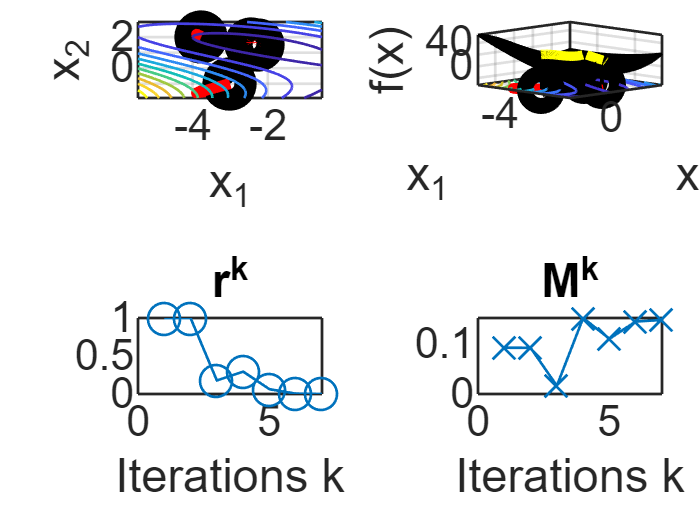

par.isd = 6;     % MNM-CMI selected
uosol(P,x1,par); % run the algorithm

Table of contents

### Output arguments.

#### `sol,` detailed information of each iteration.

Function `uosol.m` returns as the first argument a structure (that is going to be called generically structure `sol`, from "solution") with detailed information on every iteration. The information contained in this structure depends on the optimization algorithm, as described in the list below (`sol` is the generic name of the structure)

%   sol(k).x     : x^k
%   sol(k).g     : g(x^k)
%   sol(k).ng    : ||g(x^k)||
%   sol(k).d     : d^k
%   sol(k).al    : alpha^k
%   sol(k).AC    : "WC1", "WC", "SWC" ("***" if none)
%   sol(k).beta  : beta^k
%   sol(k).H     : H^K_BFGS........if isd=3
%                : h(x^k)..........if isd=3
%                : B^k.............if isd=5,6
%   sol(k).la1   : smallest eigenvalue
%                : la1(H^k_BFGS)...if isd = 3
%                : la1(h(x^k)).....if isd = 4,5,6
%   sol(k).kappa : condition number
%                : kappa(H^k_BFGS) if isd = 3
%                : kappa(h(x^k))...if isd = 4 and h(x^k) +def
%                : kappa(B^k)).....if isd = 5,6
%   sol(k).r     : r^k = e(x^(k+1))/e(x^k)
%   sol(k).M     : M^k = e(x^(k+1))/e(x^k)^2

Table of contents

For instance, in the case of the gradient method:

par.isd     = 1;        % the GM is selected.
par.logfreq = 0;        % the standard output is silenced.
[GM] = uosol(P,x1,par); % Function call

The content of structure `GM` is:

GM

GM = 1×57 struct array with fields:
    x
    g
    ng
    d
    al
    AC
    r
    M


with information related with:

- **The iterates: **`x`$=x^k$; `g`$=\nabla f^k$; `ng`$=\left\|\nabla f^k \right\|$; `d`$=d^k$; 

- **The line search:**` al`$=\alpha^k$; `AC`$=\left\lbrace \begin{array}{ll}
\textrm{"WC1"} & \textrm{if}\;\alpha^k \in A^{\textrm{WC1}} \\
\textrm{"WC"} & \textrm{if}\;\alpha^k \in A^{\textrm{WC}} \\
\textrm{"SWC"} & \textrm{if}\;\alpha^k \in A^{\textrm{SWC}} \\
"***" & \textrm{if}\;\alpha^k \not\in \;A^{\textrm{WC1}} 
\end{array}\right.$,

- **The speed of convergence:**` r`$=r^k =\frac{e\left(x^{k+1} \right)}{e\left(x^k \right)}$; `M`$=M^k =\frac{e\left(x^{k+1} \right)}{{e\left(x^k \right)}^2 }$

We can use structure `sol` to analyse the application of the algorithm. For instance, in the previous table  we see  that the (SWC) are satisfied at every iteration. Let's check that for the iteration number 30:

x=GM(30).x; d=GM(30).d; al=GM(30).al; f = P.f; g=P.g; c1=par.c1; c2=par.c2;
f(x+al*d) <= f(x) + c1*g(x+al*d)'*d*al   % (WC1)

ans = logical
   1


abs(g(x+al*d)'*d) <= c2*abs(g(x)'*d)    % (SWC2)

ans = logical
   1


Table of contents

#### `par,` default parameters.

If `uosol` is called ommiting some or all the parameters that are needed, the ommitted values are initialized with the default values and sent back through the output value of the `par` variable. For instance, let's reset the variable `par` and set only the value of the acceptability conditions of $\alpha^k$ to $\textrm{AC}=\textrm{SWC}$ and `logfreq=0:`

clear par; par.iAC = 2; par.logfreq=0; par

par = struct with fields:
        iAC: 2
    logfreq: 0


now we solve silently and get the value of the default parameters after optimization:

[sol,par]=uosol(P,x1,par); par

par = struct with fields:
        iAC: 2
    logfreq: 0
       epsG: 1.0000e-06
    maxiter: 500
        isd: 1
      almax: 1
      almin: 1.0000e-06
        rho: 0.9000
         c1: 0.0100
         c2: 0.9000
        log: 1


We can also ommit the input argument `par` when calling `uosol`, and then all default values are used:

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter =  500
   iAC = 1 (WC)
      almin = 1.0e-06, almax =  1.00, rho = 0.90, c1 = 0.01, c2 = 0.90
   isd = 1 (G)M
   ek = fk-f*
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC    ||g||        f         r        M
      1 -1.2e+02 +4.78e-01  WC +1.1e+01 +1.7e+01 +9.40e-01 +3.9e-02
      2 -2.7e+02 +3.14e-01 SWC +1.7e+01 +1.6e+01 +8.23e-03 +3.6e-04
      3 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -6.9e+00 +9.98e-01 +5.4e+00
      4 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -6.9e+00 +9.98e-01 +5.4e+00
      5 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -6.9e+00 +9.98e-01 +5.4e+00
    491 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -7.0e+00 +8.89e-01 +2.6e+02
    492 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -7.0e+00 +8.75e-01 +2.9e+02
    493 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -7.0e+00 +8.57e-01 +3.3e+02
    494 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -7.0e+00 +8.33e-01 +3.7e+02
    495 -4.1e+02 +9.12e-07 WC1 +2.0e+01 -7.0e+00 +8.00e-

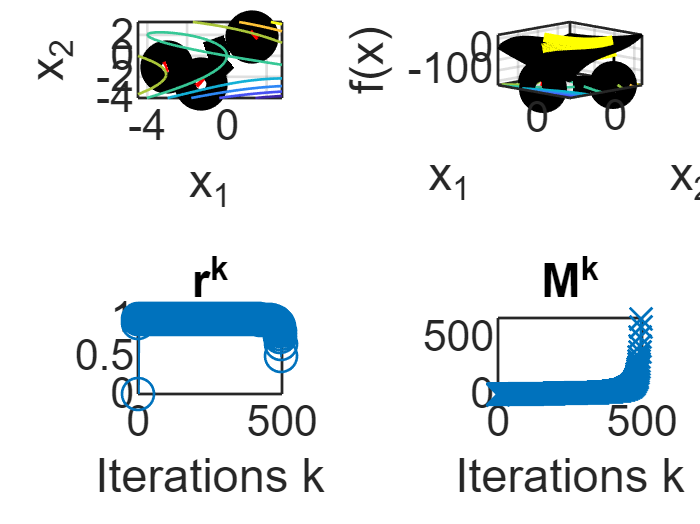

uosol(P,x1);

Table of contents

### Calls

- `uoBLS`: backtracking linesearch with Wolfe and string Wolfe contitions (**A1.2**)

- `uosolLog``: `displays the iteration log of the optimization process.

Table of contents

### Template

[sol]=uosol_st(P,x1,par);

Table of contents

## Function `uosolLog`

uosolLog


 [sol] = uosolLog(P,par,sol)

 uosol's iteration log and graphs.

   P           : f,g,h
   par         : optimization parameters
   sol (input) : ouput argument of uosol
   sol (output): same as input, extended
   Calls       : uosolPlot.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% [sol] = uosolLog(P,par,sol)
% 
% Displays a log of the optimization process every logfreq iterations, 
% writes the same log on file unosolLog.out and plots the result of the 
% optimization process with the help of function unosolPlot
%
% Input:
%
% P   : problem
% par : parameters.
% sol : information of the iterations, as found by function uosol.
%
% Iteration log:
%
%   k        : iteration number
%   g'*d     : g^k'*d^k
%   al       : alpha^k
%   AC       : acceptability of alpha^k
%            :   = *** : no WC satisfied.
%            :   = WC1 : (WC1) only
%            :   = WC  : (WC).
%            :   = SWC : (SWC).
%   ||g||    : ||g^k||.
%   f        : f^k.
%   r        : r^k = e(x^(k+1))/e(x^k).
%   M        : M^k = e(x^(k+1))/e(x^k)^2.
%   la1(H)   : la_1(H^k_BFGS)...if par.isd=3..............(BFGS)
%   la1(h)   : la_1(h(x^k)).....if par.isd=4,5,6..........(NM & MNM)
%   k(H)     : kappa(H^k_BFGS)..if par.isd=3..............(BFGS)
%   k(B)     : kappa(B^k).......if par.isd=5,6............(MNM)
%   cos(th)  : cos(theta).......if par.isd=3..............(BFGS)
%   delta    : delta............if par.isd=5..............(MNM-SD)
%   tau      : tau^k............if par.isd=6..............(MNM-SD)
%
% Output:
%
% sol : = input sol with fields la1, kappa, costh, r and , M added.
%
% Calls: uosolPlot.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Table of contents

`Example:`

First, we solve problem `P` silently:

clear par; par.isd = 3; par.logfreq=0; [sol,par]=uosol(P,x1,par);

And now we generate the interation log:

   [uosolLog]
   f  = @(x)x(1)^2+x(2)^3+3*x(1)*x(2)
   epsG = 1.0e-06, maxiter =  500
   iAC = 1 (WC)
      almin = 1.0e-06, almax =  1.00, rho = 0.90, c1 = 0.01, c2 = 0.90
   isd = 3 (BFGS)
   ek = fk-f*
   x1 = [ -3.0e+00 , -1.0e+00 ]. It k: x(k+1) <- xk + alk*dk
      k     g'*d        al  AC   la1(H)     k(H)  cos(th)    ||g||        f         r        M
      1 -1.2e+02 +4.78e-01  WC +1.0e+00 +1.0e+00 +1.0e+00 +1.1e+01 +1.7e+01 +9.42e-01 +3.8e-02
      2 -5.4e+01 +9.00e-01 SWC +1.8e-01 +6.0e+00 +8.7e-01 +1.7e+01 +1.6e+01 +3.61e-05 +1.5e-06
      3 -9.3e+02 +9.12e-07 WC1 +9.3e-02 +8.4e+01 +9.9e-01 +1.1e+01 -7.7e+00 -1.31e-02 -1.6e+01
      4 +1.2e+01 +9.12e-07 *** -1.0e-01  undef.         0 +1.1e+01 -7.7e+00 -1.31e-02 -1.6e+01
      5                                                   +1.1e+01 -7.7e+00
      k     g'*d        al  AC   la1(H)     k(H)  cos(th)    ||g||        f         r        M
   x* = [ +1.3e+00 , -1.5e+00 ]
   [uosolLog]


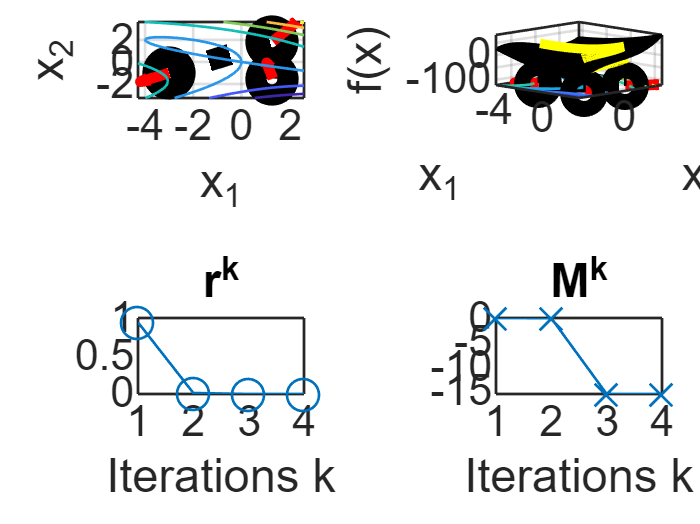

par.logfreq=1; uosolLog(P,par,sol);

Table of contents

## Function `uosolPlot`

uosolPlot


 uosolPlot(P,sol,iplot,xylim)

 Plot of P.f(x), sol.x and sol.g.

   P            : f,g,h
   sol          : sol.x, sol.g, output of uosol.
   iplot (opt.) : =1 2D level curves + {x^k}, {g^k}.
                : =2 3D f(x) + level curves + {x^k}, {g^k} (def.).
   xylim (opt.) : boundaries of the figure box ([0 0 0 0] def.).
   Calls        : none.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% uosolPlot(P, sol, iplot, xylim)
%
% Plots f(x) of two variables together with the
% sequence {x^k,g^k} generated by an optimization algorithm:
%
% Inputs:
%
% P       : f and derivatives.
% sol     : output of uosol.
%   sol.x : x^k
%   sol.g : g^k
% iplot   : optional
%         :   =1, 2D graph with level curves, {x^k}, {g^k}.
%         :   =2, 3D graph with surface f(x)+level curves + {x^k}, {g^k} (default).
% xylim   : optional
%         :   (row vector [xmin, xmax, ymin,ymax] defining the limits of the
%         :   ploting area. If [0,0,0,0] (default if ommitted) the ploting 
%         :   ranges are calculated to accomodate the whole sequence {x^k}.
%
% Calls : none.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Example:**

We can use `uosolPlot` to visualize the iterations of different algorithms, gradient method, conjugate gradient method and quasi-Newton method:

- First, we solve problem `P` silently with the three algorithms to obtain the structures `GM``, ``CGM `and `BFGS`:

clear par; par.logfreq=0; x1 = [-0.75;0.5];
par.isd = 1; [GM  ,par]=uosol(P,x1,par);
par.isd = 2; [CGM ,par]=uosol(P,x1,par);
par.isd = 3; [BFGS,par]=uosol(P,x1,par);

- And now we generate the figures:

clf reset;        % The previous figures are erased.
tiledlayout(1,3); % Grid of 1x3 figures.
nexttile; uosolPlot(P,GM)   ;title(['GM'  , ' nit=',num2str(size([  GM.x],2))])
nexttile; uosolPlot(P,CGM)  ;title(['CGM' , ' nit=',num2str(size([ CGM.x],2))])
nexttile; uosolPlot(P,BFGS) ;title(['BFGS', ' nit=',num2str(size([BFGS.x],2))])

Table of contents

## Function uoBLS

uoBLS


 [al,ACout] = uoBLS(x,d,P,par)

 Backtracking Line Search with Wolfe conditions.

   x     : x^k.
   d     : d^k.
   P     : f,g
   par   : parameters for Alg. BLS and WC.
   al    : alpha^k.
   ACout : acceptability of alpha^k.
   Calls : none.



% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% [al,ACout] = uoBLS(x,d,P,par)
%
% Algorithm BLS: Backtracking Line Search with Wolfe conditions
%
% Inputs:
%
% x           : x^k
% d           : d^k
% P           : problem.
% par         : BLS parameters
%   par.almin : al^min
%   par.almax : al^max
%   par.c1    : c1
%   par.c2    : c2
%   par.rho   : rho
%   par.iAC   : acceptability conditions
%             :   = 1: WC
%             :   = 2: SWC
%             :   = 3: WC + DC (for CGM-PR+)
%
% Outputs:
%
% al    : alpha^k
% ACout : acceptability of alpha^k:
%       :   = "WC1": al satisfies (WC1)
%       :   = "WC" : al satisfies (WC)
%       :   = "SWC": al satisfies (SWC)
%       :   = "WCD": al satisfies (WC)+(DC)
%       :   = "***": al satisfies no AC.
%
% Calls: none
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Example:**

To run function `uoBLS`, first the input parameters must be defined:

- The objective function and its gradient:

P.f = @(x) x(1)*exp(-x(1)^2-x(2)^2);
P.g = @(x) exp(-x(1)^2-x(2)^2)*[(1 - 2*x(1)^2); (-2*x(1)*x(2))];

- The current iterate $x=\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$ and search direction $d=\left\lbrack \begin{array}{c}
3\\
-3
\end{array}\right\rbrack$:

x = [-1;1]; d = [3;-3];

- The parameters for Algorithm BLS: $\alpha^{\min } ={10}^{-6}$, $\alpha^{\max } =1$, $\rho=0.9$, $c_1=0.1$, $c_2=0.9$ and $\textrm{AC}=2$ (SWC):

par.almin = 10^-6; par.almax = 1.0;
par.rho   = 0.5  ; par.c1    = 0.1; par.c2    = 0.5;
par.iAC   = 1;

Then, we run algorithm `BLS`:

[al,cWout] = uoBLS(x,d,P,par)

al = 0.2500

cWout = "WC"

We see that the step lenght $\alpha =0\ldotp 25$ is acceptable: indeed:

P.f(x+al*d) <= P.f(x) + par.c1*P.g(x)'*d*al % (WC1)

ans = logical
   1


P.g(x+al*d)'*d >= par.c2*P.g(x)'*d          % WC2

ans = logical
   1


Table of contents

### Template

[al,ACout] = uoBLS_st(x,d,P,par)

al = 1

ACout = "***"

Table of contents

## Function uoBLSPlot

uoBLSPlot


 uoBLSPlot(x,d,P,par,iBLS)

 Graphical representation of the BLS and Wolfe conditions.

   x     : x^k.
   d     : d^k.
   P     : f,g
   par   : parameters for Alg. BLS and WC.
   iBLS  : information included in the figure.
   Calls : none.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% [] = uoBLSPlot(x,d,P,par,iBLS)
%
% Graphical representation of the ELS or BLS + Wolfe conditions
%
% Input:
%
% x           : x^k
% d           : d^k
% P           : problem.
% par         : BLS parameters
%   par.almin : al^min
%   par.almax : al^max
%   par.c1    : c1
%   par.c2    : c2
%   par.rho   : rho
%   par.iAC   : acceptability conditions
%             :   = 0: ELS
%             :   = 1: WC
%             :   = 1: WC
%             :   = 2: SWC
%             :   = 3: WC + DC (for CGM-PR+)
% iBLS        : information included in the figure
%             :   =  1 : A^{WC1,WC2,SWC2}, alpha^k, legend with results
%             :   =  0 : A^{WC1,WC2,SWC2}, legend without results
%             :   = -1 : A^{WC1,WC2,SWC2}, no legend.
%
% Calls : none
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Example**

By default, `uoBLSPlot` applies Alg BLS and plots both the intervals $A^{\textrm{WC1}}$, $A^{\textrm{WC2}}$, $A^{\textrm{SWC2}}$ and the values of $\alpha^k$ at every solution.

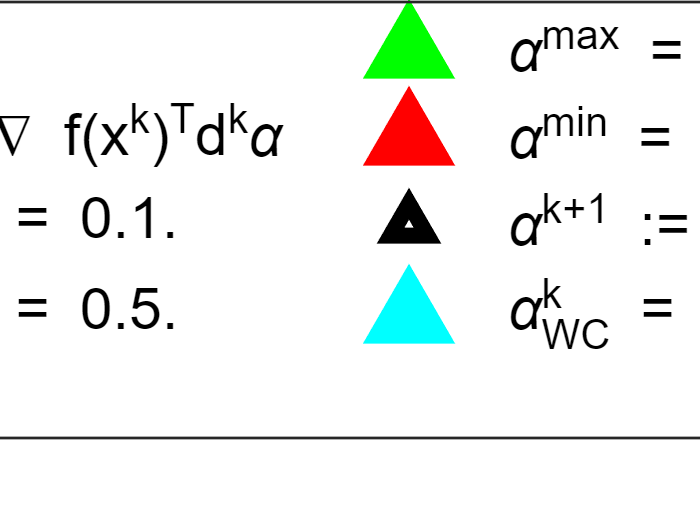

uoBLSPlot(x,d,P,par)

Table of contents

## Function uoQFsc

uoQFsc

 [P,xo] = uoQFsc(n,seed,condn)

 Random generation of strictly convex quadratic functions.

   n            : num. of variables.
   seed  (opt.) : seed              (defaul: = "shuffle").
   condn (opt.) : cond. number of Q (defaul: = 10).
   P            : f,g,h.
   xo           : strict global minimizer.
   Calls        : none.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% F.-Javier Heredia https://gnom.upc.edu/heredia
% https://creativecommons.org/licenses/by-nc/4.0/
%
% [P,xo] = uoQFsc(n,seed,condn)
%
% Random generation of strictly convex quadratic functions with integer
% entries.
%
% Inputs
% n               : num. of variables.
% seed     (opt.) : seed              (default = 0)
% condn    (opt.) : cond. number of Q (defaul: = 10)
%
% Outputs
% P  : f,g,h
% xo : strict global minimizer.
%
% Calls: none
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Example**

Function `uoQFsc` defines a strictly convex quadratic function $f\left(x\right)=\frac{1}{2}x^T \textrm{Qx}-b^T x$ (I.e.:$Q\succ 0$). For instance

n      = 5;              % number of variables
seed   = 1234;           % seed for the random generation of the elements of Q and b.
[P,xo] = uoQFsc(n);      %
P                        % quadratic function

P = struct with fields:
    f: @(x)x'*Q*x/2-b'*x
    g: @(x)Q*x-b
    h: @(x)Q


xo'                      % minimizer

ans =     0.4079   -0.0930    0.2972    0.0882   -0.1191


Q = P.h(xo)              % hessian

Q =     2.7691    2.2197    0.5191   -0.0296    1.1703
    2.2197    6.5375    0.0112    0.8993    0.4577
    0.5191    0.0112    2.8815    2.2167    2.5238
   -0.0296    0.8993    2.2167    6.1557    1.0601
    1.1703    0.4577    2.5238    1.0601    6.9085


Indeed, the hessian is +def:

eig(Q)              % +def

ans =    10.0000
    1.0000
    1.6322
    7.0231
    5.5970


The condition number $\kappa \;\left(Q\right)=\frac{\lambda_n }{\lambda_1 }$ ($=10$ by default) can be set, as well as the seed for the random generation of $Q$ (so as the same $f\left(x\right)$ can be retrieved):

condn = 1000; seed = 1234;
[P,xo]=uoQFsc(n,seed,condn); Q=P.h(xo); eig(Q), cond(Q)

ans = 1.0e+03 *

    0.0010
    1.0000
    0.3978
    0.6517
    0.7889


ans = 1.0000e+03

Table of contents